syms Gamma real

swash = [0 ; 0 ; Gamma]
% 1) declare symbols
syms x y z rp real

% 2) assume Q is already a 3×3 symbolic matrix
%    Q = [ Q11, Q12, Q13 ;
%          Q21, Q22, Q23 ;
%          Q31, Q32, Q33 ];


A = ( (x - Q(1,:)).^2 ...
    + (y - Q(2,:)).^2 ...
    + (z - Q(3,:)).^2 )';

sol = rp^2 * ones(3,1);        % 3×1 vector [rp^2; rp^2; rp^2]

% Now the three sphere equations are equivalently
%    A == b
%
% or if you need them as explicit equalities:
eqns = A == sol              % a 3×1 logical/sym array of equations

Ok now put all the spheres

%% --- NUMERIC CONVERSION FOR PLOTTING ---
r_plot   = r_val;
b_plot   = b_val;
rs_plot  = r_s_val;            % your r_s value
rp_plot  = r_p_val;        % pitch‐sphere radius
theta_plot = [0;0;0];      % your theta values

% numeric S, B, and Q
S_plot = double( subs(S,   r,   r_plot) );         
B_plot = double( subs(B,   r,   r_plot) );         
Q_plot = double( subs(Q,   [r,r_s,theta_1,theta_2,theta_3], ...
                      [r_plot,rs_plot,theta_plot.']) );

% compute L0 = S + b*B
L0 = S_plot + b_plot * B_plot;   % 3×3


%% --- PLOTTING ALL ON ONE 3D AXES ---
figure; hold on; axis equal; view(3); grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Planes, Base Circle, S→Q, Pitch Spheres & Intersections');

cols    = lines(3);
L_patch = 1.5 * r_plot;
zlim_vals = 1.5*r_plot * [-1 1];

% 1) vertical planes spanned by L0(:,k) & z‐axis
for k = 1:3
    lv = L0(:,k);
    n3 = cross(lv, [0;0;1]);
    Bplane = null(n3.');
    u_p = Bplane(:,1); v_p = Bplane(:,2);
    pc = lv/2;
    verts = [ pc + L_patch*( u_p+ v_p ), ...
              pc + L_patch*( u_p- v_p ), ...
              pc + L_patch*(-u_p- v_p ), ...
              pc + L_patch*(-u_p+ v_p ) ];
    patch('Vertices', verts.', 'Faces',[1 2 3 4], ...
          'FaceColor',cols(k,:), 'FaceAlpha',0.3, 'EdgeColor','none');
end

% 2) base circle in z=0
th = linspace(0,2*pi,360);
plot3(r_plot*cos(th), r_plot*sin(th), zeros(size(th)), ...
      'b--','LineWidth',1.5,'DisplayName','circle (z=0)');

% 3) points S and L0 endpoints
scatter3(S_plot(1,:), S_plot(2,:), S_plot(3,:), 80, 'ko','filled','DisplayName','S points');
scatter3(L0(1,:),  L0(2,:),  L0(3,:),    80, 'mo','filled','DisplayName','L endpoints');

% 4) L‐vectors in z=0
for k=1:3
  plot3([0,L0(1,k)], [0,L0(2,k)], [0,0], '-', ...
        'Color',cols(k,:), 'LineWidth',2, 'DisplayName',sprintf('L_%d',k));
end

% 5) vertical lines at L0(:,k)
for k=1:3
  plot3([L0(1,k),L0(1,k)], [L0(2,k),L0(2,k)], zlim_vals, '-', ...
        'Color',cols(k,:), 'LineWidth',2, 'DisplayName',sprintf('vert L_%d',k));
end

% 6) z‐axis
plot3([0 0],[0 0],zlim_vals, 'k-','LineWidth',2,'DisplayName','z-axis');

% 7) arrows S→Q and Q points
quiver3( S_plot(1,:),S_plot(2,:),S_plot(3,:), ...
         Q_plot(1,:)-S_plot(1,:), Q_plot(2,:)-S_plot(2,:), Q_plot(3,:)-S_plot(3,:), ...
         0,'r','LineWidth',1.2,'MaxHeadSize',0.5,'DisplayName','S→Q');
scatter3(Q_plot(1,:), Q_plot(2,:), Q_plot(3,:), 80, 'r','filled','DisplayName','Q tips');

% 8) pitch spheres at each Q_plot(:,k)
[XS,YS,ZS] = sphere(36);
for k = 1:3
    cx = Q_plot(1,k);
    cy = Q_plot(2,k);
    cz = Q_plot(3,k);
    XC = cx + rp_plot * XS;
    YC = cy + rp_plot * YS;
    ZC = cz + rp_plot * ZS;
    surf(XC, YC, ZC, 'FaceAlpha',0.2, 'EdgeColor','none', 'FaceColor',cols(k,:));
end

% 9) intersections: each sphere ∩ its plane
for k = 1:3
    % plane normal for leg k
    n_plane = cross(L0(:,k), [0;0;1]);
    n_plane = n_plane / norm(n_plane);
    % distance from sphere center Q(:,k) to the plane
    d = dot(n_plane, Q_plot(:,k));
    % center of intersection circle
    c = Q_plot(:,k) - d * n_plane;
    % radius of intersection circle
    r_c = sqrt(max(rp_plot^2 - d^2, 0));
    % two in‐plane axes
    Bp = null(n_plane.');
    % parametrize circle
    phi = linspace(0,2*pi,200);
    V = c + r_c*(Bp(:,1)*cos(phi) + Bp(:,2)*sin(phi));
    % plot circle
    plot3(V(1,:), V(2,:), V(3,:), '-', ...
          'Color',cols(k,:), 'LineWidth',2, ...
          'DisplayName',sprintf('int circle %d',k));
end

% finalize legend (remove duplicates)
lh = legend('Location','bestoutside');
[~, idx] = unique(lh.String);
lh.String = lh.String(sort(idx));

hold off;

Derriving the equation of the three circles shown above

% 1) declare your symbolic vars
syms x y z rp real


tmp_1 = ( (x - Q(1,:)).^2 ...
    + (y - Q(2,:)).^2 ...
    + (z - Q(3,:)).^2 )' ;   % 3×1

% 4) build the right‐hand sides b_k = rp^2
tmp_2 = rp^2 * ones(3,1);        % 3×1

% 5) pack them into your final variable
pitch_values = tmp_1 == tmp_2       % 3×1 array of symbolic equations

%% 2) assume S,B,Q already in your workspace as 3×3 sym-matrices
%    (if not, re-build them here symbolically)

% e3 = z‐axis unit
e3 = [0;0;1];
for k = 1:3
  n(k) = simplify( cross(L(:,k), e3).' / norm(cross(L(:,k), e3)) );
  plane_eqn(k) = n(k)*(x + y + z) == 0;    % adjust to n(k)'*[x;y;z]==0
end
pitch_values = [ plane_eqn.' ; pitch_values ]



There is no way to do this symbolically as it takes too long, so insead we must subsitute in values

L = subs(L, [r, b], [r_val, b_val]);
Q = subs(Q, [r, r_s], [r_val, r_s_val]);
r_p = r_p_val;

OK now we find the neutral height to make this easier

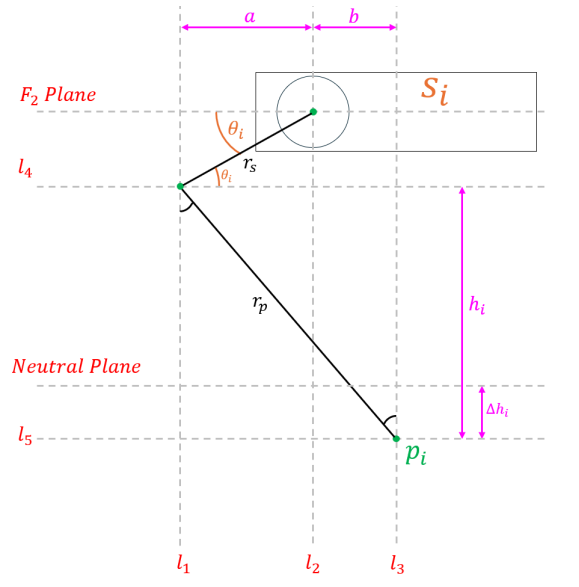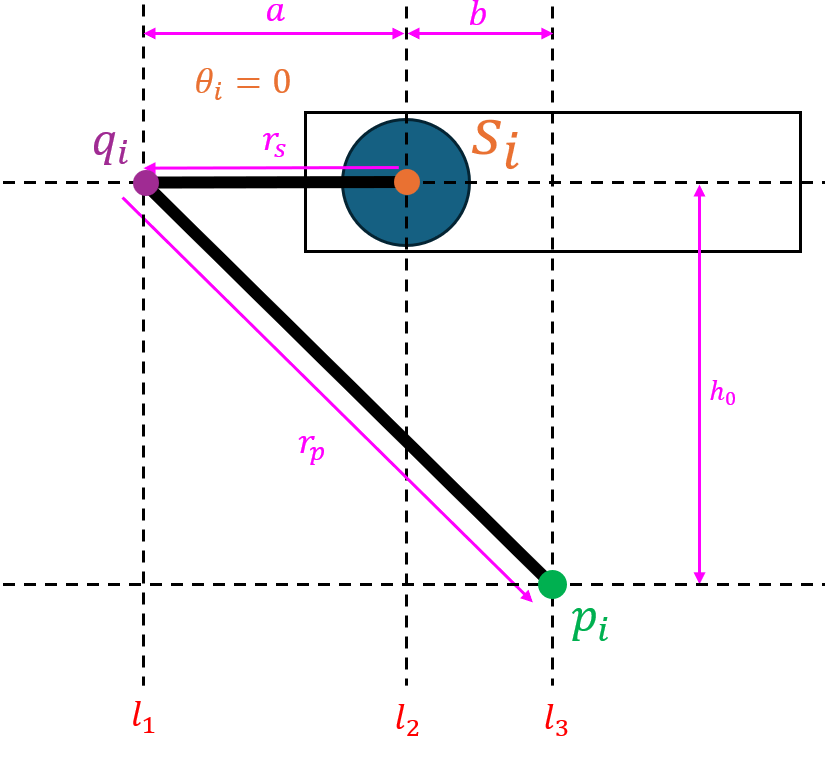

h_0 = subs(sqrt(r_p^2 - (b + r_s)^2 ), [b, r_s], [b_val, r_s_val])

